clear variables
addpath("Demo\");

## Constants

% Setup constants for Usamas signal generator
EstimationConstants = struct( ...
    'Samplerate', 24000, ...
    'AmountOfMicrophones', 6, ...
    'UCARadius', 0.40 / 2, ...
    'SpeedOfSound', 343, ...
    'SoundOutputOffset', 0.116 / 2, ... % From Genelec 8010A datasheet (half depth)
    'AlphaOffset', 60, ... % Offset betweeen x-axis and mic 1 in degrees
    'AmountOfTaus', 3000, ...
    'AmountOfPhis', 720, ...
    'AmountOfOmegas', 12000, ...
    'MinDistance', 0.5, ...
    'MaxDistance', 2.0, ...
    'Betas', [] ...
    );

RIRConstants = struct( ...
    'SpeedOfSound', EstimationConstants.SpeedOfSound, ...
    'Samplerate', EstimationConstants.Samplerate, ...
    'RoomDimensions', [16, 16, 16], ...
    'Length', [], ...
    'MicrophoneType', 'omnidirectional', ...
    'Order', -1, ...
    'ReverberationTime', 0.6 ... % T60
    );

SignalConstants = struct(...
    'SignalLength', 20000, ...
    'BurstLength', 1500, ...
    'AmountOfMicrophones', EstimationConstants.AmountOfMicrophones, ...
    'SNR', 100, ...
    'SDNR', 100, ...
    'SpeedOfSound', EstimationConstants.SpeedOfSound, ...
    'MicPoses', [], ...
    'DiffuseNoiseSource', 'allMotors_70_mic1.wav' ...
    );

## Precalculations

EstimationConstants.Betas = UCAangles(EstimationConstants.AmountOfMicrophones, EstimationConstants.AlphaOffset); % In radians

Omegas = linspace(0, EstimationConstants.Samplerate, EstimationConstants.AmountOfOmegas); % In Hz
OmegasAngular = Omegas * 2 * pi;
OmegasAngular(ceil(EstimationConstants.AmountOfOmegas/2+1):end) = OmegasAngular(ceil(EstimationConstants.AmountOfOmegas/2+1):end) - EstimationConstants.Samplerate * 2 * pi;

Phis = linspace(0, deg2rad(359), EstimationConstants.AmountOfPhis); % In radians

SteeringVectors = SteeringVector(Phis, OmegasAngular, EstimationConstants);
[~, wDSHermitian] = BeamformerDS(SteeringVectors, EstimationConstants, ...
    "Plot", false, "LookingDirection", 200);

Taus = linspace(EstimationConstants.MinDistance, EstimationConstants.MaxDistance, EstimationConstants.AmountOfTaus); % In meters
TausSample = Taus * 2 / EstimationConstants.SpeedOfSound * EstimationConstants.Samplerate; % In samples


% Relative Cartesian positions for RIR
for Microphone = 1 : EstimationConstants.AmountOfMicrophones
    % For our calculations we need 3D
    MicPoses(Microphone, :) = EstimationConstants.UCARadius * [cos(EstimationConstants.Betas(Microphone)), sin(EstimationConstants.Betas(Microphone)), 0]; 
    % But for signal generation we need 2D
    SignalConstants.MicPoses(Microphone, :) = MicPoses(Microphone, 1:2);
end

EstimationConstants.OmegasAngular = OmegasAngular;
EstimationConstants.Phis = Phis;
EstimationConstants.TausSample = TausSample;
EstimationConstants.wDSHermitian = wDSHermitian;

## Main loop

AmountOfPoints = 31;
IterationsPerPoint = 1;

### Distance variation

DistanceVector = linspace(EstimationConstants.MinDistance, EstimationConstants.MaxDistance, AmountOfPoints);
SourcePos = [repelem(RIRConstants.RoomDimensions(1)/2, AmountOfPoints); DistanceVector; repelem(RIRConstants.RoomDimensions(3)/2, AmountOfPoints)];

Distances = zeros(1, AmountOfPoints);

for Index = 1 : AmountOfPoints
    ReceiverPos(:, :) = transpose(SourcePos(:, Index) + transpose(MicPoses));
    
    Estimations = Simulator(SourcePos(:, Index), ReceiverPos, IterationsPerPoint, ...
            EstimationConstants, RIRConstants, SignalConstants);
    
    Distances(Index) = mean(Estimations.Distance);
end

Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 

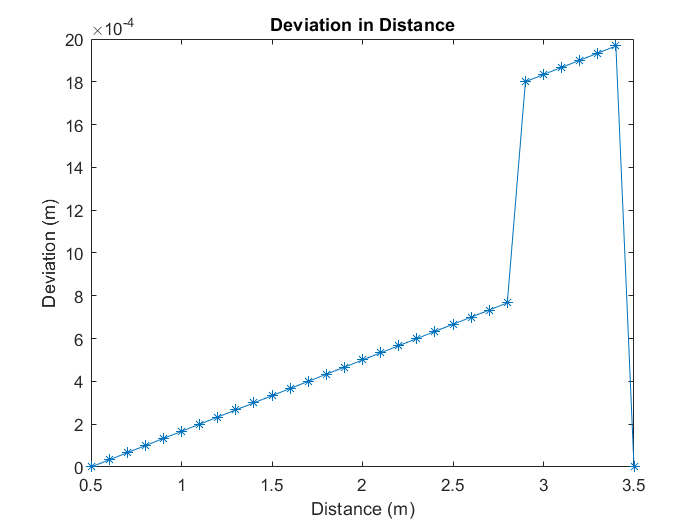


Deviation = Distances - DistanceVector;
figure
plot(DistanceVector, Deviation, "Marker","*", "LineStyle", "-")
title("Deviation in Distance");
xlabel("Distance (m)")
ylabel("Deviation (m)")
xlim([DistanceVector(1) DistanceVector(end)])


save("DistanceVariation", "Deviation")

### SNR variation

SourcePos(3) = RIRConstants.RoomDimensions(3) / 2;

AmountOfSNRs = 41;
SNRVector = linspace(-20, 20, AmountOfSNRs);

SuccesRates = zeros(1, AmountOfSNRs);

MaxRoomSize = 20;
MinRoomSize = 5;

for Index = 1 : AmountOfSNRs
    SignalConstants.SNR = SNRVector(Index);
    
    DistanceDeviations = zeros(1, AmountOfPoints);
    AcceptableDists = zeros(1, AmountOfPoints);
    for Point = 1 : AmountOfPoints
        RIRConstants.RoomDimensions(1:2) = (MaxRoomSize - MinRoomSize) * rand(1, 2) + MinRoomSize;
        SourcePos(1) = RIRConstants.RoomDimensions(1) / 2;
        SourcePos(2) = (EstimationConstants.MaxDistance - EstimationConstants.MinDistance) * rand() + EstimationConstants.MinDistance;
        ReceiverPos = SourcePos + MicPoses;
        
        
        Estimations = Simulator(SourcePos, ReceiverPos, IterationsPerPoint, ...
            EstimationConstants, RIRConstants, SignalConstants);
        
        ActualPoint = SourcePos(2) * [cosd(270) sind(270)];
        AcceptableDists(Point) = 0.1 * SourcePos(2);
        EstimatedPoint = Estimations.Distance * [cosd(Estimations.Angle), sind(Estimations.Angle)];
        DistanceDeviations(Point) = norm(EstimatedPoint - ActualPoint);
    end
    
    WithinRange = DistanceDeviations < AcceptableDists;
    SuccesRates(Index) = sum(WithinRange) / length(WithinRange) * 100;
end

Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 

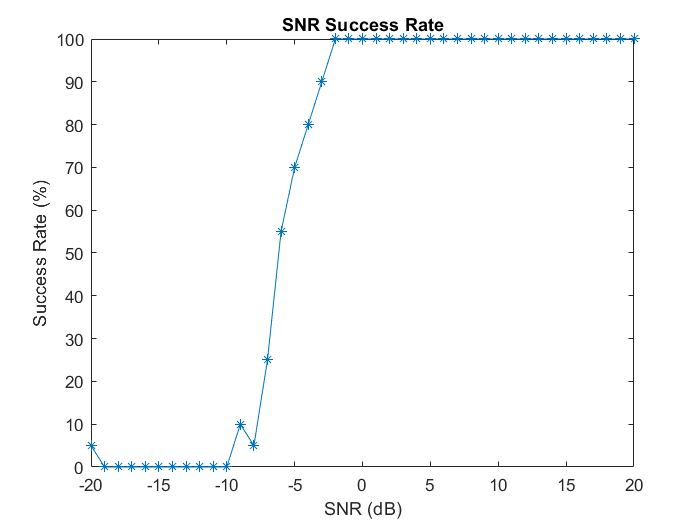


figure
plot(SNRVector, SuccesRates, "Marker","*", "LineStyle", "-")
title("SNR Success Rate");
ylabel("Success Rate (%)")
xlabel("SNR (dB)")


save("SuccessRate", "SuccesRates");

function AverageEstimations = Simulator(SourcePos, ReceiverPos, NIterations, EstimationConstants, RIRConstants, SignalConstants)
    arguments
        SourcePos (1, 3)
        ReceiverPos (:, 3)
        NIterations int16
        EstimationConstants struct
        RIRConstants struct
        SignalConstants struct
    end
    
    RIRs = rir(SourcePos, ReceiverPos, RIRConstants);
    
    Angles = zeros(NIterations, 1);
    Distances = zeros(NIterations, 1);
    
    for Iteration = 1 : NIterations
        Signals = signals(RIRs, SignalConstants);
    
        ProbeFFT = FFT(Signals.ProbeSound, ...
            "Plot", false, ...
            "Samplerate", EstimationConstants.Samplerate, ...
            "nFFT", EstimationConstants.AmountOfOmegas);
        
        Zbar = CalculateZbar(ProbeFFT, EstimationConstants.TausSample, EstimationConstants);
        
        ReceivedFFT = FFT(Signals.ObservedReflections, "nFFT", EstimationConstants.AmountOfOmegas);

        Ybar = CalculateYbar(ReceivedFFT, EstimationConstants.wDSHermitian, EstimationConstants, ...
            "Plot", false);
        
        CostMatrix = CostFunction(Ybar, Zbar, EstimationConstants, ...
            "Plot", false);
        
        [Angles(Iteration), Distances(Iteration)] = Estimator(EstimationConstants.Phis, EstimationConstants.TausSample, CostMatrix, EstimationConstants);
    end
    
    AverageEstimations.Angle = Angles;
    AverageEstimations.Distance = Distances;
end

function output = NormToRange(RandomVariables, Min, Max)
arguments
    RandomVariables
    Min {isscalar(Min)}
    Max {isscalar(Max)}
end
    output = RandomVariables .* (Max - Min) + Min;
end